## I/ Récupération des données:

#### I.2/ Visualisation des données:

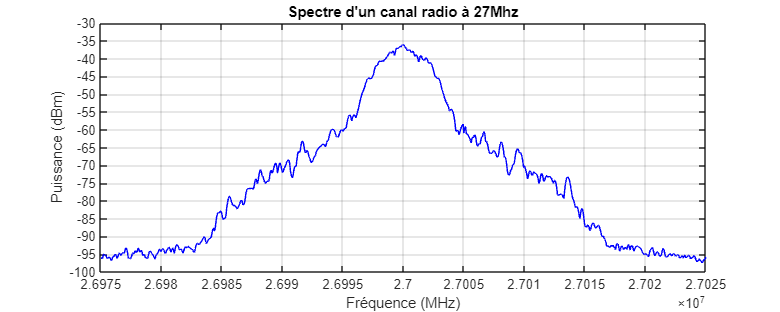

f = MachineModule; %importation des fréquences
Pdbm = SSA3050XR; %importation des puissances

figure('Position',[200 200 1000 400]);
plot(f, Pdbm,'b'); %affiche le spectre du canal en bleu
title("Spectre d'un canal radio à 27Mhz"); %donne un titre au graphe
xlabel("Fréquence (MHz)");
ylabel("Puissance (dBm)");
axis([2.6975e7 2.7025e7 -100 -30]); %permet de régler les axes
yticks(-100:5:-30); %permet de régler l'échelle verticale
grid on;

## **II/ Lissage des données:**

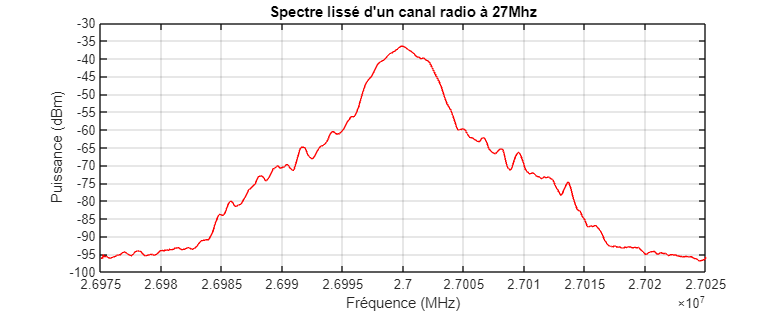

Ns = length(Pdbm); % nombre de cases du tableau
K = 4; % ordre du filtre

PLdbm = Pdbm; %tableau lissé du spectre

%calcul du spectre lissé
for n = K+1:Ns-K
    PLdbm(n) = sum(Pdbm(n-K:n+K))/(2*K+1);
end

figure('Position',[200 200 1000 400]);
plot(f, PLdbm,'r'); %affiche le spectre lissé du canal en rouge
title("Spectre lissé d'un canal radio à 27Mhz"); %donne un titre au graphe
xlabel("Fréquence (MHz)");
ylabel("Puissance (dBm)");
axis([2.6975e7 2.7025e7 -100 -30]); %permet de régler les axes
yticks(-100:5:-30); %permet de régler l'échelle verticale
grid on;

## **III/ Détermination de la bande occupée à -20dB:**

[A, index] = max(PLdbm) %Amplitude max du canal & index

A = -36.5160

index = 374

Ffreq = f(index) % fréquence de l'amplitude max

Ffreq = 26999860



PLCanal = []; %définition du tableau des puissances du canal à -20dBm
Ftab = []; %définition du tableau des fréquences du canal à -20dBm

%calcul du canal à -20dBm
for i = 1:Ns
    if PLdbm(i) >= A - 20   % Si la valeur est supérieur à A-20, on la garde dans le tableau
        PLCanal = [PLCanal PLdbm(i)];
        Ftab = [Ftab f(i)];
    end
end

F1 = Ftab(1) %récupère la première fréquence du canal à -20

F1 = 26995660

F2 = Ftab(end) %récupère la dernière fréquence du canal à -20

F2 = 27004060


FreqCanal = F2 - F1

FreqCanal = 8400

## **IV/ Calcul de la puissance du canal:**

Pw = 10.^(PLCanal/10).*1e-3; %convertion de la puissance en Watt

RBW = 300; %Résolution BandWidth (récupérer via le fichier csv)

DSP = Pw./RBW; %calcul du tableau de la RBW pour le canal

PCanal = sum(DSP); %calcul de la puissance du canal en W
PCanaldbm = 10*log10(PCanal/1e-6) %calcul de la puissance du canal en dBm

PCanaldbm = -14.7024

## **V/ Présentation des résultats:**

figure('Position',[200 200 1000 400]);
plot(f, Pdbm,'b'); %affiche le spectre du canal en bleu
title("Spectre d'un canal radio à 27Mhz"); %donne un titre au graphe
xlabel("Fréquence (MHz)");
ylabel("Puissance (dBm)");
axis([2.6975e7 2.7025e7 -100 -30]); %permet de régler les axes
yticks(-100:5:-30); %permet de régler l'échelle verticale
grid on;


figure('Position',[200 200 1000 400]);
plot(f, PLdbm,'r'); %affiche le spectre lissé du canal en rouge
title("Spectre lissé d'un canal radio à 27Mhz"); %donne un titre au graphe
xlabel("Fréquence (MHz)");
ylabel("Puissance (dBm)");
axis([2.6975e7 2.7025e7 -100 -30]); %permet de régler les axes
yticks(-100:5:-30); %permet de régler l'échelle verticale
str = strcat('Puissance du canal en dBm = ',string(PCanaldbm),'dBm')

str = "Puissance du canal en dBm =-14.7024dBm"

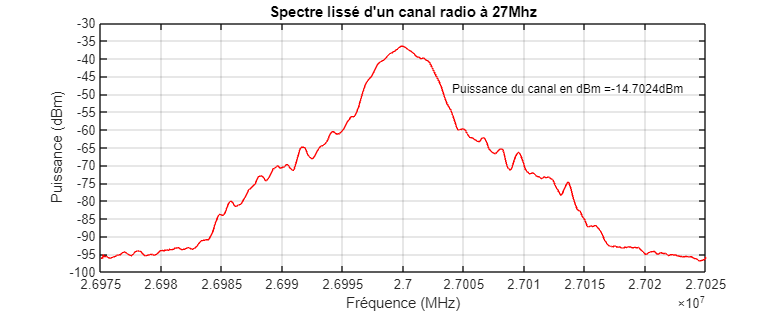

posy=min(PLdbm)+0.80*(max(PLdbm)-min(PLdbm));
text(2.7004e7,posy,str,FontSize=9);
grid on;